# MIMO Channel Estimation with interpolation

## Steps:

- Load the dataset: LS estimated channel at the pilot location, and the actual MIMO channel

- Split them into train, validation and test set

- Split them into real and imag parts

- Interpolate the Input data to match the size of output

- Save the weights and simulate to compare it with LS and MMSE techniques

### Load the dataset:

data_input = load('combined_data_1.mat');
data_output = load('combined_labels_1.mat');

for i =1:size(data_input.combined_data{3,1},3)
    x=norm(data_input.combined_data{3,1}(:,:,i),'fro');
    if(x==0)
    data_input.combined_data{3,1}(:,:,i)=data_input.combined_data{3,1}(:,:,i)*10^9;
    else
    data_input.combined_data{3,1}(:,:,i)=data_input.combined_data{3,1}(:,:,i)/x;
    end
    x=norm(data_output.combined_labels{3,1}(:,:,i),'fro');
    if(x==0)
    data_output.combined_labels{3,1}(:,:,i)=data_output.combined_labels{3,1}(:,:,i)*10^9;
    else
    data_output.combined_labels{3,1}(:,:,i)=data_output.combined_labels{3,1}(:,:,i)/x;
    end
end

### 2. Split into train, validation and test 

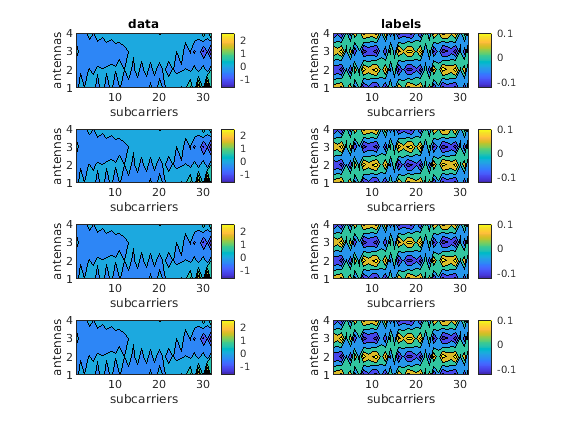

% Taking Nant = 4
Nant = size(data_input.combined_data{3,1},1);
Ncarr = size(data_output.combined_labels{3,1},2);
pilot_cols = 1:4:16;
Nuser = size(data_input.combined_data{3,1},3);
data_input2 = zeros(Nant,Ncarr,Nuser);
for i=1:Nuser
    data_input2(:,:,i) = pilot_interpolate(data_input.combined_data{3,1}(:,:,i),pilot_cols,Nant,Ncarr);
end
train_data = zeros(Nant,2*Ncarr,30000); 
train_label= zeros(Nant,2*Ncarr,30000);
val_data = zeros(Nant,2*Ncarr,1500); 
val_label = zeros(Nant,2*Ncarr,1500); 
%test_data = zeros(Nant,2*Ncarr,1500);
%test_label = zeros(Nant,2*Ncarr,1500);
real_pos = 1:2:32;
train_data(:,real_pos,:) = real(data_input2(:,:,1:30000));
train_label(:,real_pos,:) = real(data_output.combined_labels{3,1}(:,:,1:30000));
val_data(:,real_pos,:) = real(data_input2(:,:,30001:31500));
val_label(:,real_pos,:) = real(data_output.combined_labels{3,1}(:,:,30001:31500));
%test_data(:,real_pos,:) = real(data_input2(:,:,31501:33000));
%test_label(:,real_pos,:) = real(data_output.combined_labels{3,1}(:,:,31501:33000));


train_data(:,real_pos+1,:) = imag(data_input2(:,:,1:30000));
train_label(:,real_pos+1,:) = imag(data_output.combined_labels{3,1}(:,:,1:30000));
val_data(:,real_pos+1,:) = imag(data_input2(:,:,30001:31500));
val_label(:,real_pos+1,:) = imag(data_output.combined_labels{3,1}(:,:,30001:31500));
%test_data(:,real_pos+1,:) = imag(data_input2(:,:,31501:33000));
%test_label(:,real_pos+1,:) = imag(data_output.combined_labels{3,1}(:,:,31501:33000));
train_data = reshape(train_data,[Nant,2*Ncarr,1,size(train_data,3)]);
train_label = reshape(train_label,[Nant,2*Ncarr,1,size(train_label,3)]);
val_data = reshape(val_data,[Nant,2*Ncarr,1,size(val_data,3)]);
val_label = reshape(val_label,[Nant,2*Ncarr,1,size(val_label,3)]);

plot_random_samples(train_data,train_label,'contour','training_data.png');

### 3. Training the network

Starting parallel pool (parpool) using the 'local' profile ...
connected to 4 workers.


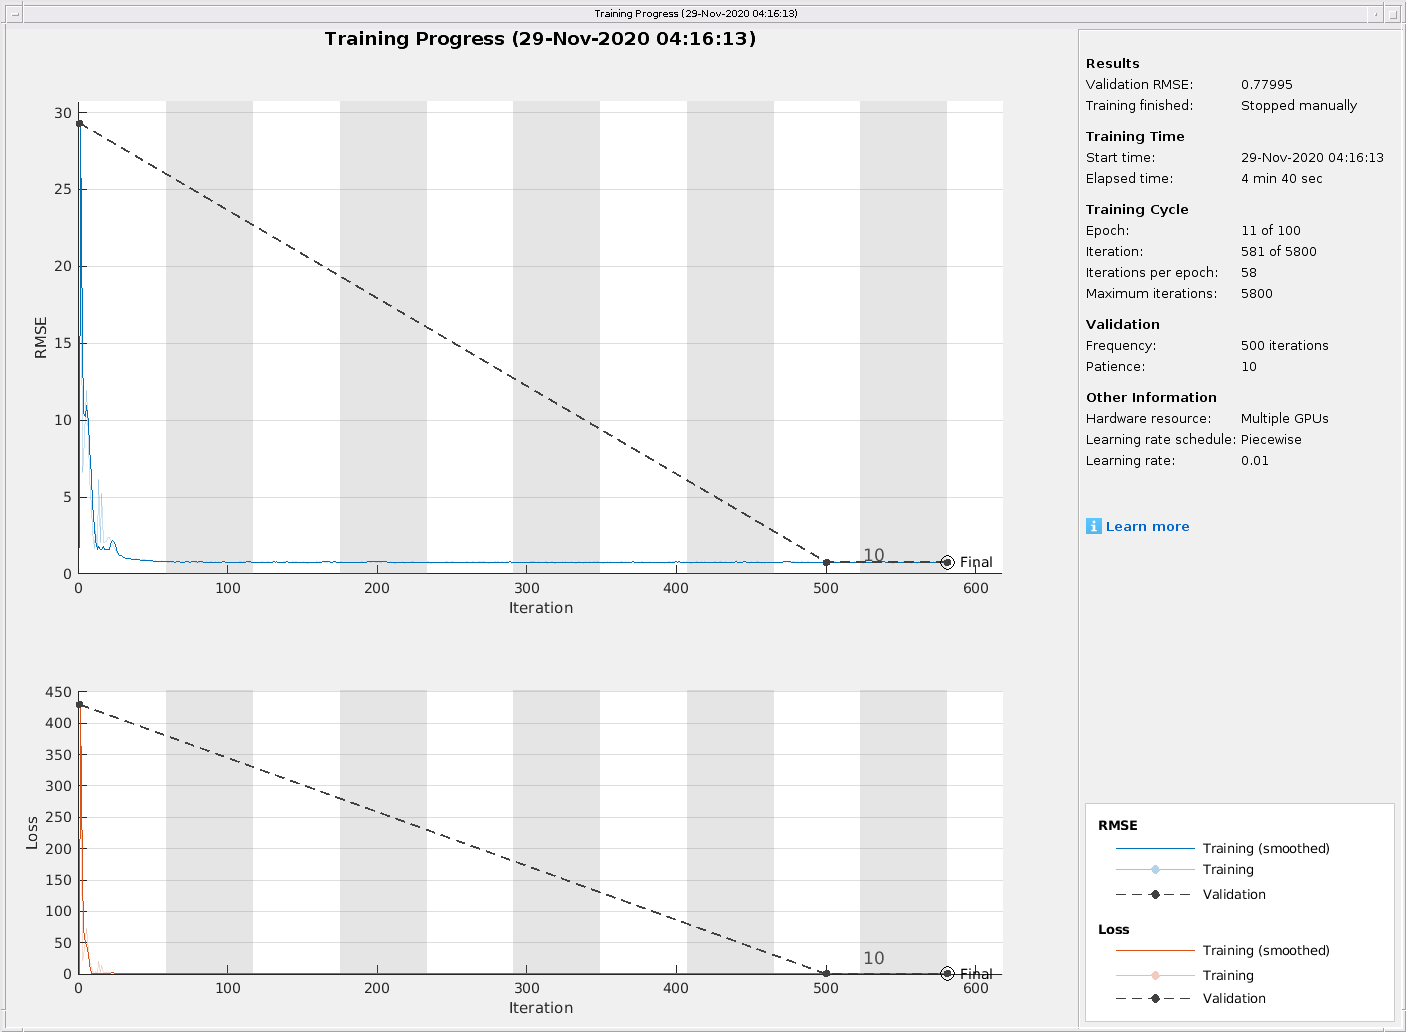

mimo_net =   DAGNetwork with properties:

         Layers: [77×1 nnet.cnn.layer.Layer]
    Connections: [77×2 table]


mimo_trainingInfo = struct with fields:
      TrainingLoss: [1×581 double]
      TrainingRMSE: [1×581 double]
    ValidationLoss: [1×581 double]
    ValidationRMSE: [1×581 double]
     BaseLearnRate: [1×581 double]


layers_1 = [...
        imageInputLayer([Nant 2*Ncarr 1],'Normalization','none','Name','Input')
        convolution2dLayer(10,128,'Padding','same','Name','cnn1')
        batchNormalizationLayer('Name','b1')
        reluLayer('Name','reLu1')
        convolution2dLayer(7,64,'Padding','same','Name','cnn2')
        batchNormalizationLayer('Name','b2')
        reluLayer('Name', 'reLu2')
        convolution2dLayer(5, 32,'Padding','same','Name','cnn_new')
        reluLayer('Name','relu_new')
        convolution2dLayer(3,16,'Padding','same','Name','cnn_new1')
        batchNormalizationLayer('Name','b3')
        reluLayer('Name', 'reLu5')
        convolution2dLayer(2,8,'Padding','same','Name','cnn_new2')
        batchNormalizationLayer('Name','b4')
        reluLayer('Name', 'reLu6')
        convolution2dLayer(5,1,'Padding','same','Name','cnn3')
        %batchNormalizationLayer('Name','b3')
        %reluLayer('Name','reLu3')...,
        ];

lgraph = layerGraph(layers_1);
layers_dn = dncnn_layers();
lgraph = addLayers(lgraph,layers_dn);
lgraph = connectLayers(lgraph,'cnn3','reLu3');
lgraph = connectLayers(lgraph,'reLu3','add_1/in2');

batchSize = 512;
valFrequency = 500;

   options = trainingOptions('adam', ...
    'ExecutionEnvironment','multi-gpu',...
    'InitialLearnRate',0.01, ...
    'MaxEpochs',100, ...
    'Shuffle','every-epoch', ...
    'Verbose',false, ...
    'Plots','training-progress', ...
    'MiniBatchSize',batchSize, ...
    'ValidationData',{val_data, val_label}, ...
    'ValidationFrequency',valFrequency, ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',100,...
    'LearnRateDropFactor',0.1,...
    'L2Regularization',1e-5,...
    'ValidationPatience',10);
    
    [mimo_net,mimo_trainingInfo] = trainNetwork(train_data, ...
                                          train_label,lgraph,options)

### 4. Simulate and Compare with MMSE

snr = 0:4:40; %SNR in db
n=10000;
test_label = (data_output.combined_labels{3,1}(:,:,n:n+6000));
pilot_angles = linspace(0, pi/2,length(pilot_cols));
pilot = exp(1j*pilot_angles);
pilot_channel = data_output.combined_labels{3,1}(:,pilot_cols,n:n+6000);
test_label_dl = zeros(Nant,2*Ncarr,6001);
test_label_dl(:,real_pos,:) = real(data_output.combined_labels{3,1}(:,:,n:n+6000));
test_label_dl(:,real_pos+1,:) = imag(data_output.combined_labels{3,1}(:,:,n:n+6000));
test_data_dl = zeros(Nant,2*Ncarr);
warning('off','all')
LS = [];
MMSE =[];
DL = [];
for snrdb=snr
    ls_rmse = 0;
    mmse_rmse = 0;
    dl_rmse = 0;
    for i=1:3000
        Pr_avg = norm(abs(pilot_channel(:,:,i)))^2;
        SNR    = 10^(.1*snrdb);
        Pn     = (Pr_avg/SNR)/2;
        rec = pilot_channel(:,:,i).*pilot;
        rec = rec + sqrt(Pn)*randn(size(rec,1), size(rec,2)) +...
        1i*sqrt(Pn)*randn(size(rec,1), size(rec,2)); % Add noise;
       
        [H_est_ls,H_est_mmse] = mimo_mmse_ls(Ncarr,Nant,rec,pilot,pilot_channel(:,:,i),pilot_cols);
        Rec = pilot_interpolate(rec,pilot_cols,Nant,Ncarr);
        test_data_dl(:,real_pos) = real(Rec);
        test_data_dl(:,real_pos+1) = imag(Rec);
        %test_data_dl = reshape(test_label_dl,[size(test_data_dl,1),size(test_data_dl,2),1]);
        H_est_dl = predict(mimo_net,test_data_dl);
        dl_rmse =  dl_rmse + sqrt(mean(abs(H_est_dl - test_label_dl(:,:,i)).^2,'all'));
        ls_rmse = ls_rmse + sqrt(mean(abs(H_est_ls - test_label(:,:,i)).^2,'all'));
        mmse_rmse = mmse_rmse + sqrt(mean(abs(H_est_mmse - test_label(:,:,i)).^2,'all'));
        
        
    end
    LS = [LS ls_rmse/3000];
    MMSE = [MMSE mmse_rmse/3000];
    DL = [DL dl_rmse/3000];
    
end


figure1 = figure

figure1 =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [508 656 583 437]
       Units: 'pixels'

  Show all properties


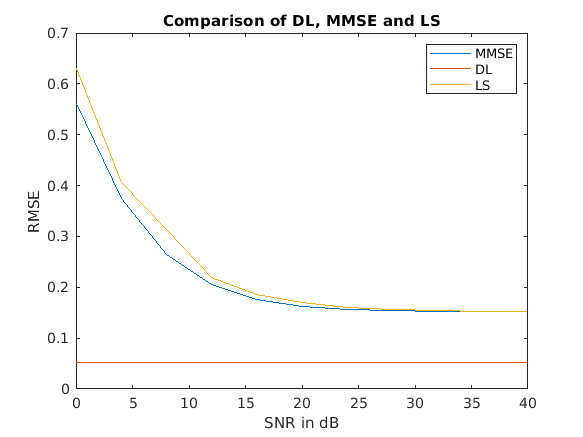

plot(snr,LS,snr,DL,snr,MMSE)
xlabel('SNR in dB')
ylabel('RMSE')
title('Comparison of DL, MMSE and LS')
legend('LS','DL','MMSE')
savefig(figure1,'comparison.fig')

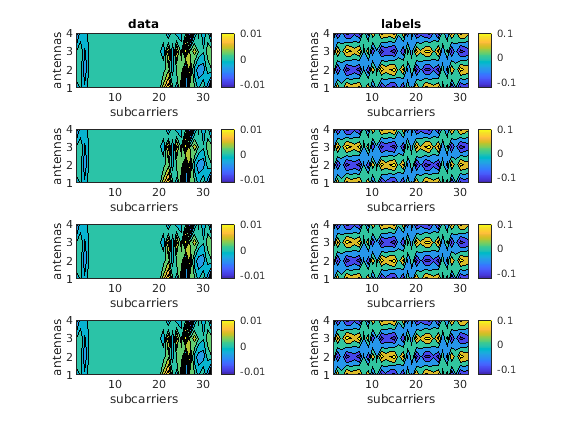


val_data2 = predict(mimo_net,val_data);
plot_random_samples(val_data2,val_label,'contour','val_data.png');